# **Concave Hexagon**

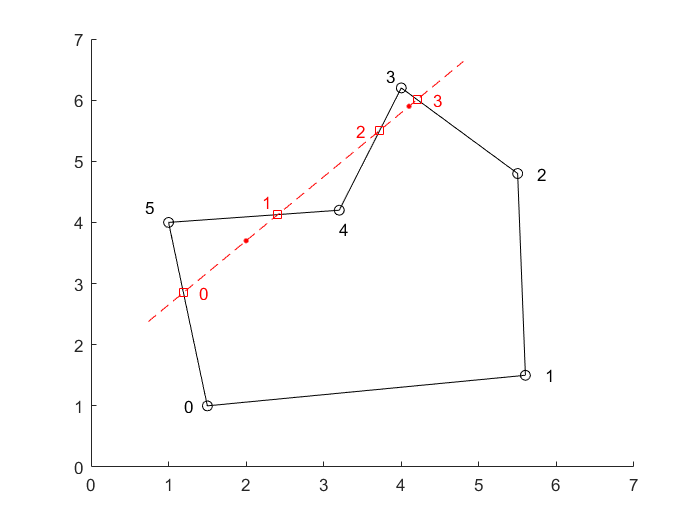

width = 1.0;

color1 = [45, 147, 250] / 255;
color2 = [2, 189, 8] / 255;
color3 = [240, 236, 10] / 255;

points = [
    1.5, 1.0;
    5.6, 1.5;
    5.5, 4.8;
    4.0, 6.2;
    3.2, 4.2;
    1.0, 4.0];
polygon = polyshape(points);
segment = [2.0, 3.7; 4.1, 5.9];
intersection = [
    1.191, 2.852
    2.408, 4.128
    3.721, 5.503
    4.204, 6.009];

tangent = segment(2, :) - segment(1, :);
start = segment(1, :) - 3*tangent/5;
fine  = segment(2, :) + tangent/3;

figure;
hold on;

plot(polygon, "FaceColor", "w", "");
plot([start(1), fine(1)], [start(2), fine(2)], 'r--');
plot(points(:, 1),points(:, 2), 'ko');
plot(intersection(:, 1), intersection(:, 2), 'rs');
plot(segment(:, 1), segment(:, 2), 'r.', "MarkerSize", 9);

text(points(1, 1) - 0.3, points(1, 2), "0");
text(points(2, 1) + 0.25, points(2, 2), "1");
text(points(3, 1) + 0.25, points(3, 2), "2");
text(points(4, 1) - 0.2, points(4, 2) + 0.2, "3");
text(points(5, 1), points(5, 2) - 0.3, "4");
text(points(6, 1) - 0.3, points(6, 2) + 0.25, "5");

text(intersection(1, 1) + 0.2, intersection(1, 2), "0", "Color", "r");
text(intersection(2, 1) - 0.2, intersection(2, 2) + 0.2, "1", "Color", "r");
text(intersection(3, 1) - 0.3, intersection(3, 2), "2", "Color", "r");
text(intersection(4, 1) + 0.2, intersection(4, 2), "3", "Color", "r");

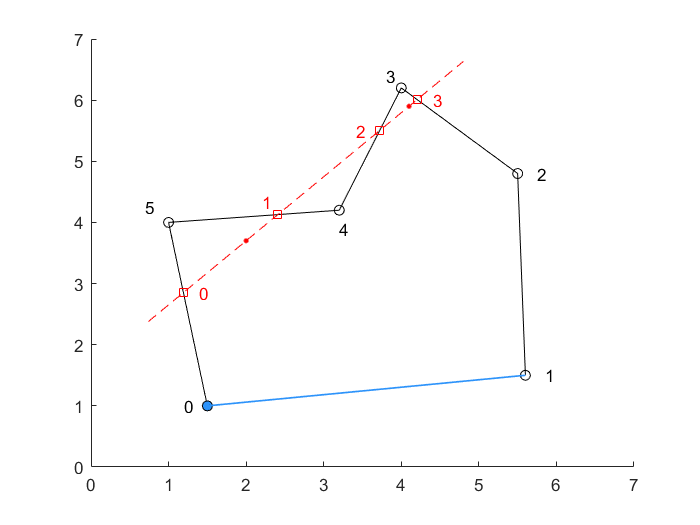


plot(points(1, 1), points(1, 2), "ko", "MarkerFaceColor", color1)
plot([points(1, 1), points(2, 1)], [points(1, 2), points(2, 2)], "Color", color1, "LineWidth", width);

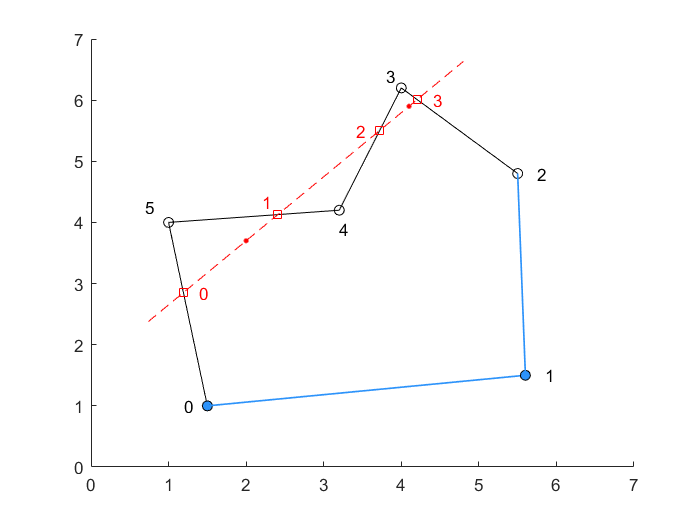


plot(points(2, 1), points(2, 2), "ko", "MarkerFaceColor", color1)
plot([points(3, 1), points(2, 1)], [points(3, 2), points(2, 2)], "Color", color1, "LineWidth", width);

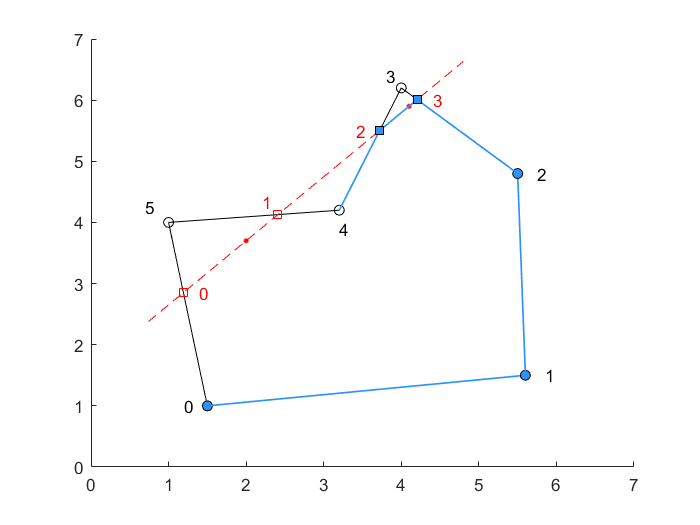


plot(points(3, 1), points(3, 2), "ko", "MarkerFaceColor", color1)
plot([points(3, 1), intersection(4, 1)], [points(3, 2), intersection(4, 2)], "Color", color1, "LineWidth", width);
plot([intersection(3, 1), intersection(4, 1)], [intersection(3, 2), intersection(4, 2)], "Color", color1, "LineWidth", width);
plot([points(5, 1), intersection(3, 1)], [points(5, 2), intersection(3, 2)], "Color", color1, "LineWidth", width);
plot(intersection(3, 1), intersection(3, 2), "ks", "MarkerFaceColor", color1);
plot(intersection(4, 1), intersection(4, 2), "ks", "MarkerFaceColor", color1);

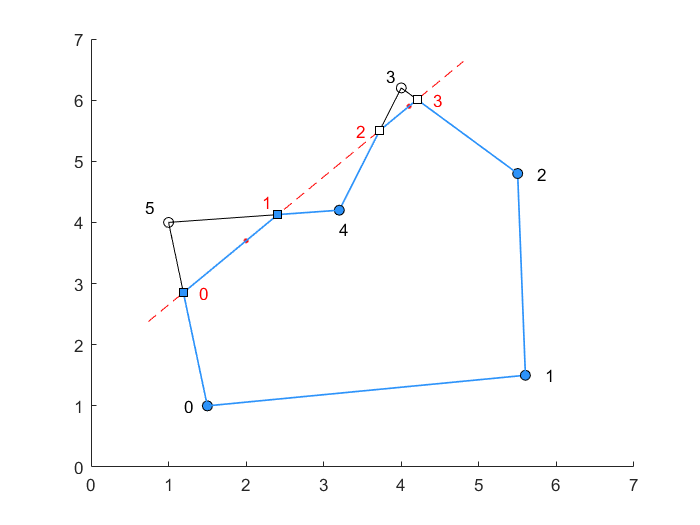

plot(intersection(3, 1), intersection(3, 2), "ks", "MarkerFaceColor", "auto");
plot(intersection(4, 1), intersection(4, 2), "ks", "MarkerFaceColor", "auto");

plot(points(5, 1), points(5, 2), "ko", "MarkerFaceColor", color1);
plot([points(5, 1), intersection(2, 1)], [points(5, 2), intersection(2, 2)], "Color", color1, "LineWidth", width);
plot([intersection(1, 1), intersection(2, 1)], [intersection(1, 2), intersection(2, 2)], "Color", color1, "LineWidth", width);
plot([points(1, 1), intersection(1, 1)], [points(1, 2), intersection(1, 2)], "Color", color1, "LineWidth", width);
plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", color1);
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", color1);

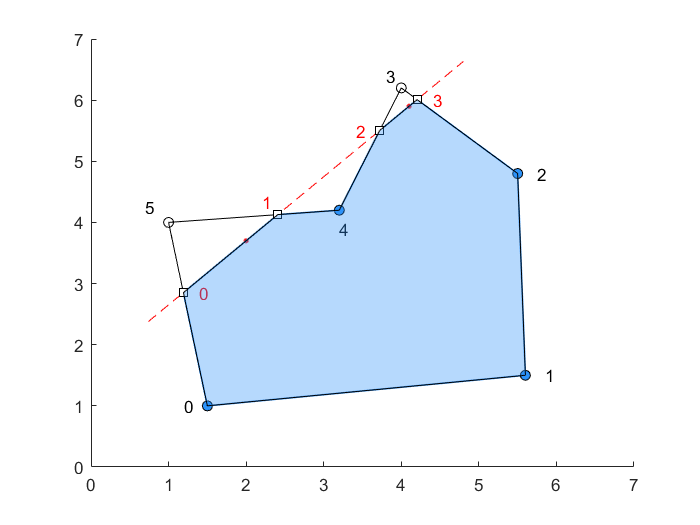

plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", "auto");
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", "auto");

points1 = [
    1.5, 1.0;
    5.6, 1.5;
    5.5, 4.8;
    4.204, 6.009;
    3.721, 5.503;
    3.2, 4.2;
    2.408, 4.128;
    1.191, 2.852];
polygon1 = polyshape(points1);
plot(polygon1, "FaceColor", color1);

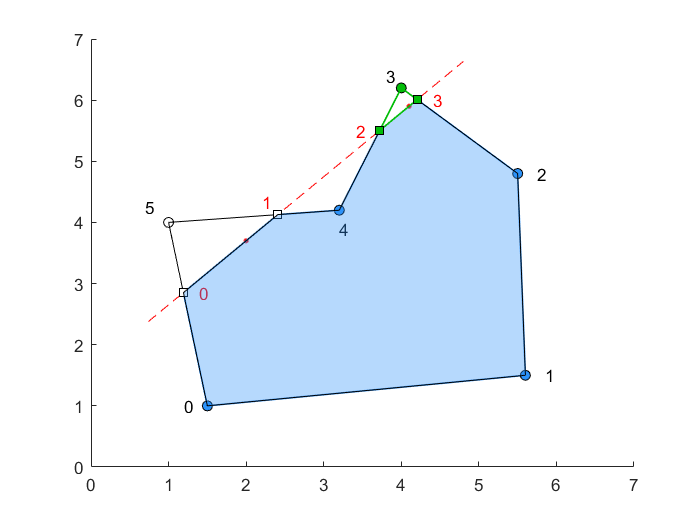


plot(points(4, 1), points(4, 2), "ko", "MarkerFaceColor", color2);
plot([points(4, 1), intersection(3, 1)], [points(4, 2), intersection(3, 2)], "Color", color2, "LineWidth", width);
plot([intersection(3, 1), intersection(4, 1)], [intersection(3, 2), intersection(4, 2)], "Color", color2, "LineWidth", width);
plot([points(4, 1), intersection(4, 1)], [points(4, 2), intersection(4, 2)], "Color", color2, "LineWidth", width);
plot(intersection(3, 1), intersection(3, 2), "ks", "MarkerFaceColor", color2);
plot(intersection(4, 1), intersection(4, 2), "ks", "MarkerFaceColor", color2);

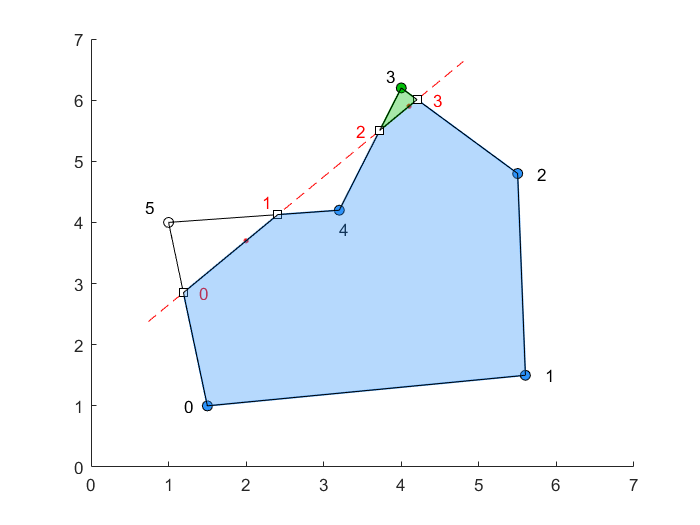

plot(intersection(3, 1), intersection(3, 2), "ks", "MarkerFaceColor", "auto");
plot(intersection(4, 1), intersection(4, 2), "ks", "MarkerFaceColor", "auto");

points2 = [
    4.0, 6.2;
    3.721, 5.503;
    4.204, 6.009];
polygon2 = polyshape(points2);
plot(polygon2, "FaceColor", color2);

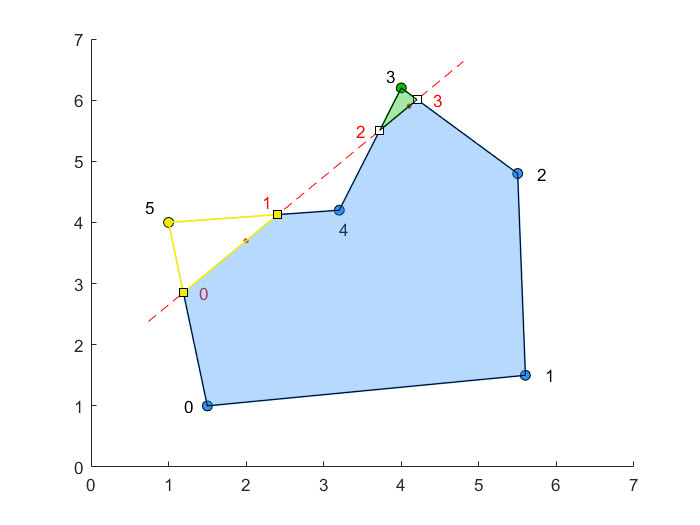


plot(points(6, 1), points(6, 2), "ko", "MarkerFaceColor", color3);
plot([points(6, 1), intersection(1, 1)], [points(6, 2), intersection(1, 2)], "Color", color3, "LineWidth", width);
plot([intersection(1, 1), intersection(2, 1)], [intersection(1, 2), intersection(2, 2)], "Color", color3, "LineWidth", width);
plot([points(6, 1), intersection(2, 1)], [points(6, 2), intersection(2, 2)], "Color", color3, "LineWidth", width);
plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", color3);
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", color3);

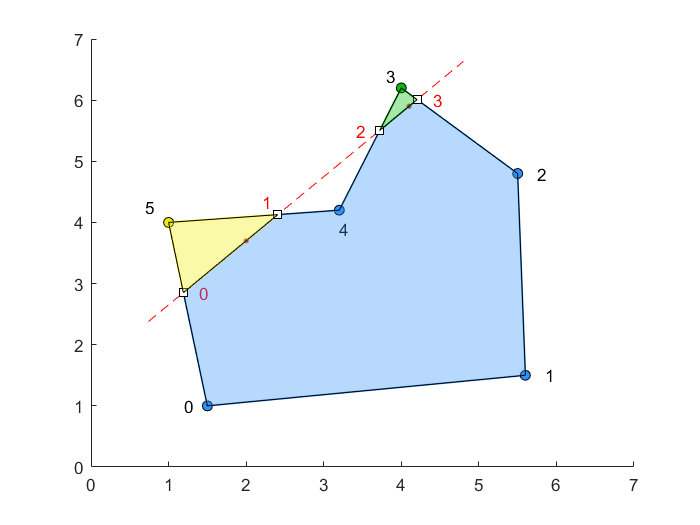

plot(intersection(1, 1), intersection(1, 2), "ks", "MarkerFaceColor", "auto");
plot(intersection(2, 1), intersection(2, 2), "ks", "MarkerFaceColor", "auto");

points3 = [
    1.0, 4.0;
    1.191, 2.852;
    2.408, 4.128];
polygon3 = polyshape(points3);
plot(polygon3, "FaceColor", color3);

hold off;